% Problem 6: Quadratic fit
substrate = [0.00, 0.34, 0.69, 1.03, 1.38, 1.72, 2.07, 2.41, 2.76, 3.10,...
             3.45, 3.79, 4.14, 4.48, 4.83, 5.17, 5.52, 5.86, 6.21, 6.55,...
             6.90, 7.24, 7.59, 7.93, 8.28, 8.62, 8.97, 9.31, 9.66, 10.00];
activity = [-0.48, 2.48, 4.03, 6.22, 10.33, 11.19, 12.39, 13.54, 15.29, 16.44,...
            17.39, 18.68, 18.68, 19.64, 19.44, 19.74, 20.46, 20.53, 20.28,...
            18.83, 19.22, 17.35, 15.80, 13.78, 12.59, 10.39, 8.27, 5.73,...
            4.24, 2.82];

coeffs = polyfit(substrate, activity, 2);
y_fit = polyval(coeffs, substrate);
Rsq = 1 - sum((activity - y_fit).^2) / sum((activity - mean(activity)).^2);

fprintf('Problem 6 Best fit function: %.3fx^2 + %.3fx + %.3f\n', coeffs(1), coeffs(2), coeffs(3));

Problem 6 Best fit function: -0.781x^2 + 8.072x + -0.707


fprintf('R squared value: %.4f\n', Rsq);

R squared value: 0.9903


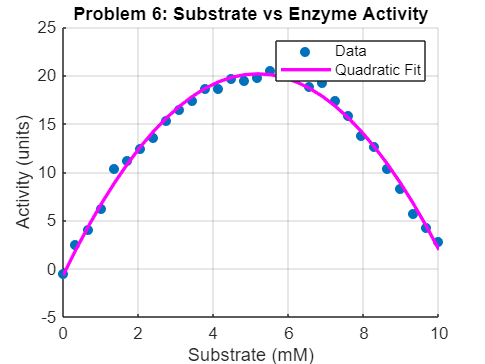


figure;
scatter(substrate, activity, 'filled'); hold on;
plot(substrate, y_fit, 'm', 'LineWidth', 2);
title('Problem 6: Substrate vs Enzyme Activity');
xlabel('Substrate (mM)');
ylabel('Activity (units)');
legend('Data', 'Quadratic Fit');
grid on;